clc; 
clear ;
close all;

tic
load ryan3_gen_data.mat
toc 

Elapsed time is 9.707199 seconds.


% https://kr.mathworks.com/help/matlab/ref/load.html
%load('ryan3_gen_data.mat','battery_dataset')

# 변수 추출

cap = zeros();
Vd = zeros();
RUL = zeros();
%Vd = [1:100];
battery_dataset(1).QDischargeSmooth

ans =     1.0479
    1.0478
    1.0477
    1.0476
    1.0475
    1.0474
    1.0473
    1.0472
    1.0471
    1.0470


battery_dataset(1).Vd

ans =     2.0166    3.2957    3.2329    3.2020    3.1854    3.1754    3.1689    3.1642    3.1605    3.1572    3.1545    3.1518    3.1495    3.1474    3.1452    3.1431    3.1411    3.1390    3.1368    3.1348    3.1327    3.1306    3.1286    3.1265    3.1243    3.1220    3.1199    3.1175    3.1152    3.1127    3.1103    3.1079    3.1052    3.1028    3.1002    3.0975    3.0949    3.0921    3.0895    3.0866    3.0838    3.0809    3.0780    3.0750    3.0719    3.0687    3.0654    3.0621    3.0585    3.0549
    2.0161    3.2949    3.2324    3.2014    3.1848    3.1749    3.1686    3.1637    3.1599    3.1568    3.1540    3.1515    3.1492    3.1469    3.1448    3.1427    3.1407    3.1386    3.1365    3.1345    3.1325    3.1304    3.1283    3.1262    3.1239    3.1217    3.1195    3.1171    3.1148    3.1125    3.1101    3.1076    3.1050    3.1025    3.0999    3.0972    3.0947    3.0919    3.0891    3.0863    3.0836    3.0806    3.0777    3.0747    3.0716    3.0684    3.0652    3.0619    3.0582   

size(battery_dataset(1).QDischargeSmooth)

ans =    428     1


length(battery_dataset(1).QDischargeSmooth)

ans = 428


idxAll = (1:length(battery_dataset));
idxTrainValid = [ idxTrain idxValid ];
idxTrainAll = []; %zeros();
idxValidAll = []; %zeros();
idxTestAll = []; %zeros();


j =1;
startIndx = j ;
GenerateFrameList = @(A,S,N) A+S*(0:N-1);

for i = 1: length(idxAll)
        
    cap_temp = battery_dataset(i).QDischargeSmooth;
    RUL_temp = linspace(battery_dataset(i).cycle_life,1,battery_dataset(i).cycle_life)';
    leng = length(cap_temp);
    %startIndx = j ;
    % https://kr.mathworks.com/matlabcentral/answers/478553-how-can-i-have-a-starting-number-a-step-size-then-the-number-of-numbers-i-need-in-a-1d-array
    append_index = GenerateFrameList(startIndx,1,leng);
    
    Vd_temp = battery_dataset(i).Vd ;
    Ic_temp = battery_dataset(i).Ic ;
    %Vd = [Vd ; Vd_temp];
    if  i == 1
        Vd = Vd_temp;
        cap = cap_temp; 
        Ic = Ic_temp;
        RUL = RUL_temp;
    else
        Vd = vertcat(Vd,Vd_temp);
        %cap = vertcat(cap,cap_temp);
        Ic = vertcat(Ic,Ic_temp);
        RUL = vertcat(RUL,RUL_temp);
    end
    
    if any(idxTrain(:) == i) 
       % https://kr.mathworks.com/matlabcentral/answers/283821-add-single-element-to-array-or-vector
       idxTrainAll =  [idxTrainAll append_index ] ;
    end
    if any(idxValid(:) == i) 
       idxValidAll =  [idxValidAll append_index ] ;
    end
    if any(idxTest(:) == i) 
       idxTestAll =  [idxTestAll append_index ] ;
    end
    %Vd(i) = Vd_temp;
    
    startIndx = startIndx + leng;
end


idxTrainAll

idxTrainAll =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


idxValidAll

idxValidAll =         2793        2794        2795        2796        2797        2798        2799        2800        2801        2802        2803        2804        2805        2806        2807        2808        2809        2810        2811        2812        2813        2814        2815        2816        2817        2818        2819        2820        2821        2822        2823        2824        2825        2826        2827        2828        2829        2830        2831        2832        2833        2834        2835        2836        2837        2838        2839        2840        2841        2842


idxTestAll

idxTestAll =         4962        4963        4964        4965        4966        4967        4968        4969        4970        4971        4972        4973        4974        4975        4976        4977        4978        4979        4980        4981        4982        4983        4984        4985        4986        4987        4988        4989        4990        4991        4992        4993        4994        4995        4996        4997        4998        4999        5000        5001        5002        5003        5004        5005        5006        5007        5008        5009        5010        5011


cap

cap =     1.0479
    1.0478
    1.0477
    1.0476
    1.0475
    1.0474
    1.0473
    1.0472
    1.0471
    1.0470


Vd

Vd =     2.0166    3.2957    3.2329    3.2020    3.1854    3.1754    3.1689    3.1642    3.1605    3.1572    3.1545    3.1518    3.1495    3.1474    3.1452    3.1431    3.1411    3.1390    3.1368    3.1348    3.1327    3.1306    3.1286    3.1265    3.1243    3.1220    3.1199    3.1175    3.1152    3.1127    3.1103    3.1079    3.1052    3.1028    3.1002    3.0975    3.0949    3.0921    3.0895    3.0866    3.0838    3.0809    3.0780    3.0750    3.0719    3.0687    3.0654    3.0621    3.0585    3.0549
    2.0161    3.2949    3.2324    3.2014    3.1848    3.1749    3.1686    3.1637    3.1599    3.1568    3.1540    3.1515    3.1492    3.1469    3.1448    3.1427    3.1407    3.1386    3.1365    3.1345    3.1325    3.1304    3.1283    3.1262    3.1239    3.1217    3.1195    3.1171    3.1148    3.1125    3.1101    3.1076    3.1050    3.1025    3.0999    3.0972    3.0947    3.0919    3.0891    3.0863    3.0836    3.0806    3.0777    3.0747    3.0716    3.0684    3.0652    3.0619    3.0582    

Ic

Ic =          0    4.3998    4.4002    4.4002    4.4003    4.3998    4.3999    4.4003    4.4001    4.4003    4.4004    4.4003    4.3999    4.4002    4.3999    4.4000    4.3998    4.4001    4.4004    4.4000    4.3999    4.4004    4.3999    4.4001    4.3999    4.3999    4.3995    4.3998    4.3999    4.3999    4.4001    4.3999    4.4000    4.3996    4.4001    4.4001    4.3998    4.3993    4.4007    4.3997    4.3997    4.4000    4.4003    4.3997    4.4001    4.4001    4.4000    4.3999    4.4008    4.3999
         0    4.3998    4.3999    4.4002    4.3997    4.4004    4.3997    4.4002    4.4000    4.4005    4.4002    4.3999    4.3995    4.4000    4.4001    4.3998    4.3999    4.4000    4.4001    4.3999    4.4015    4.3998    4.4000    4.4002    4.3999    4.4002    4.4000    4.4000    4.4002    4.4003    4.4000    4.3999    4.4001    4.4003    4.4000    4.3998    4.3999    4.3996    4.4003    4.3989    4.4000    4.4002    4.4000    4.3998    4.4000    4.4000    4.3999    4.4001    4.4002    

RUL

RUL =    428
   427
   426
   425
   424
   423
   422
   421
   420
   419


% https://kr.mathworks.com/matlabcentral/answers/80480-how-do-i-take-the-average-of-every-n-values-in-a-vector
blockSize = [1, 5] % 다섯개를 묶어서.

blockSize =      1     5


meanFilterFunction = @(theBlockStructure) mean2(theBlockStructure.data(:))

meanFilterFunction = function_handle with value:
    @(theBlockStructure)mean2(theBlockStructure.data(:))



Ic_new = blockproc(Ic, blockSize, meanFilterFunction)

Ic_new =     3.5201    4.4001    4.4002    4.4001    4.4000    4.3998    4.3999    4.3999    4.3999    4.4001    4.4000    4.4000    4.3999    4.4000    2.9013    1.0000    1.0000    0.0994         0         0
    3.5199    4.4002    4.3999    4.3999    4.4003    4.4001    4.4001    4.3997    4.4000    4.4001    4.3999    4.4002    4.4000    4.2403    2.9039    1.0001    1.0000    0.0985         0         0
    3.5200    4.4000    4.3998    4.4000    4.3999    4.4000    4.4001    4.3999    4.4000    4.4000    4.3999    4.3999    4.3999    4.4000    2.8984    1.0000    1.0000    0.0986         0         0
    3.5198    4.4000    4.4000    4.4000    4.4001    4.4001    4.4000    4.3999    4.4000    4.4001    4.4001    4.4000    4.4002    4.1381    2.8975    0.9998    0.9999    0.0946         0         0
    3.5200    4.4001    4.4001    4.4000    4.4001    4.3999    4.4000    4.4000    4.4000    4.4000    4.3996    4.4000    4.3997    4.3998    2.8970    0.9998    1.0000    0.0949       

%clear Ic  

Vd_new = blockproc(Vd, blockSize, meanFilterFunction)

Vd_new =     2.9865    3.1652    3.1497    3.1389    3.1285    3.1174    3.1053    3.0921    3.0779    3.0619    3.0428    3.0185    2.9853    2.9360    2.8528    2.6893    2.2963    1.9998    1.9998    1.9998
    2.9859    3.1648    3.1493    3.1386    3.1282    3.1171    3.1050    3.0918    3.0776    3.0616    3.0425    3.0182    2.9851    2.9357    2.8525    2.6892    2.2980    1.9999    1.9999    1.9999
    2.9866    3.1656    3.1499    3.1392    3.1287    3.1175    3.1054    3.0922    3.0779    3.0619    3.0428    3.0184    2.9853    2.9359    2.8522    2.6877    2.2909    2.0001    2.0001    2.0001
    2.9862    3.1650    3.1495    3.1388    3.1283    3.1172    3.1051    3.0919    3.0776    3.0617    3.0425    3.0182    2.9850    2.9355    2.8519    2.6878    2.2935    1.9997    1.9996    1.9996
    2.9862    3.1649    3.1494    3.1387    3.1283    3.1173    3.1051    3.0919    3.0778    3.0618    3.0426    3.0183    2.9851    2.9357    2.8521    2.6878    2.2933    2.0001    2.0

%clear Vd  

idxTrainAll_t_vt = idxTrainAll;
idxValidAll_t_vt = idxValidAll;
idxTestAll_t_vt = idxTestAll;

save('ryan3_gen_data.mat','Ic_new','-append');
save('ryan3_gen_data.mat','Vd_new','-append');
save('ryan3_gen_data.mat','cap','-append');
save('ryan3_gen_data.mat','Ic','-append');
save('ryan3_gen_data.mat','Vd','-append');
save('ryan3_gen_data.mat','idxTrainAll_t_vt','-append');
save('ryan3_gen_data.mat','idxValidAll_t_vt','-append');
save('ryan3_gen_data.mat','idxTestAll_t_vt','-append');
save('ryan3_gen_data.mat','RUL','-append');


%x = Vd_new;
x = Ic_new;
y = RUL;
[ynorm,ymax,ymin,yrate,xnorm,xmax,xmin,xrate] = minmax_norm_new(y,x);



clear Ic Vd
clear Ic_new Vd_new 
clear battery_dataset

# 학습/검증 및 테스트 데이타 추출

x_trainValid = xnorm([idxTrainAll idxValidAll],:)

x_trainValid =     0.4398    0.5497    0.5498    0.5497    0.5497    0.5497    0.5497    0.5497    0.5497    0.5498    0.5497    0.5497    0.5497    0.5497    0.3625    0.1249    0.1249    0.0124         0         0
    0.4398    0.5498    0.5497    0.5497    0.5498    0.5498    0.5497    0.5497    0.5497    0.5497    0.5497    0.5498    0.5497    0.5298    0.3628    0.1250    0.1249    0.0123         0         0
    0.4398    0.5497    0.5497    0.5497    0.5497    0.5497    0.5498    0.5497    0.5497    0.5497    0.5497    0.5497    0.5497    0.5497    0.3621    0.1249    0.1249    0.0123         0         0
    0.4398    0.5497    0.5497    0.5497    0.5497    0.5498    0.5497    0.5497    0.5497    0.5498    0.5497    0.5497    0.5498    0.5170    0.3620    0.1249    0.1249    0.0118         0         0
    0.4398    0.5497    0.5498    0.5497    0.5498    0.5497    0.5497    0.5497    0.5497    0.5497    0.5497    0.5497    0.5497    0.5497    0.3620    0.1249    0.1249    0.0119 

x_test = xnorm([idxTestAll],:)

x_test =     0.5997    0.7497    0.7496    0.7497    0.7496    0.7497    0.7496    0.5247    0.3748    0.3748    0.3748    0.3748    0.3748    0.3748    0.2749    0.1249    0.1250    0.0132         0         0
    0.5998    0.7497    0.7496    0.7496    0.7496    0.7497    0.7496    0.5247    0.3748    0.3748    0.3748    0.3748    0.3748    0.3748    0.2749    0.1249    0.1249    0.0130         0         0
    0.5997    0.7496    0.7497    0.7497    0.7497    0.7496    0.7497    0.5248    0.3748    0.3748    0.3748    0.3748    0.3748    0.3748    0.2749    0.1249    0.1249    0.0128         0         0
    0.5998    0.7497    0.7496    0.7496    0.7497    0.7497    0.7497    0.5247    0.3748    0.3748    0.3748    0.3748    0.3748    0.3748    0.2748    0.1249    0.1249    0.0124         0         0
    0.5998    0.7496    0.7497    0.7497    0.7496    0.7496    0.7497    0.5247    0.3748    0.3748    0.3748    0.3748    0.3748    0.3748    0.2749    0.1249    0.1249    0.0123       


y_trainValid = ynorm([idxTrainAll idxValidAll])

y_trainValid =     0.3650
    0.3641
    0.3632
    0.3624
    0.3615
    0.3607
    0.3598
    0.3590
    0.3581
    0.3573


y_test = ynorm([idxTestAll])

y_test =     0.2692
    0.2684
    0.2675
    0.2667
    0.2658
    0.2650
    0.2641
    0.2632
    0.2624
    0.2615


# 선형회귀

tic
mdl = fitlm(x_trainValid,y_trainValid)

mdl = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15 + x16 + x17 + x18 + x19 + x20

Estimated Coefficients:
                   Estimate        SE         tStat       pValue   
                   _________    _________    _______    ___________

    (Intercept)      0.35169    0.0097665      36.01    2.7133e-279
    x1             -0.047798     0.014404    -3.3185     0.00090601
    x2             -0.032413     0.018185    -1.7824       0.074688
    x3              -0.21615     0.017472    -12.371     4.3618e-35
    x4               0.16227     0.014826     10.945     7.7348e-28
    x5              -0.21989     0.019736    -11.141     8.7442e-29
    x6             -0.0

toc

Elapsed time is 3.093157 seconds.


%mdlr = fitlm(x_trainValid,y_trainValid,'linear', ...
%    'RobustOpts','on');

mdlr = fitlm(x_trainValid,y_trainValid,'quadratic', ...
    'RobustOpts','on');




% x19 유의하지 않음.
coeff = mdl.Coefficients.Estimates

coeff =     0.3517
   -0.0478
   -0.0324
   -0.2161
    0.1623
   -0.2199
   -0.0569
   -0.0843
    0.2115
   -0.2393


coeffr = mdlr.Coefficients.Estimate

coeffr =     1.2074
   -0.0852
   -1.2694
    2.5044
   -2.8201
    0.3426
    0.5044
   -0.0256
    0.1382
   -0.4806


x_trainValid(1,:)

ans =     0.4398    0.5497    0.5498    0.5497    0.5497    0.5497    0.5497    0.5497    0.5497    0.5498    0.5497    0.5497    0.5497    0.5497    0.3625    0.1249    0.1249    0.0124         0         0


training set 에서는 정말 잘 동작함.

RMSE 가 정말 작다.

yhat = x_trainValid*coeff(2:21)+coeff(1)

yhat =     0.4490
    0.4577
    0.4475
    0.4580
    0.4433
    0.4403
    0.4403
    0.4385
    0.4368
    0.4355


%yhatr = x_trainValid*coeffr(2:21)+coeffr(1)

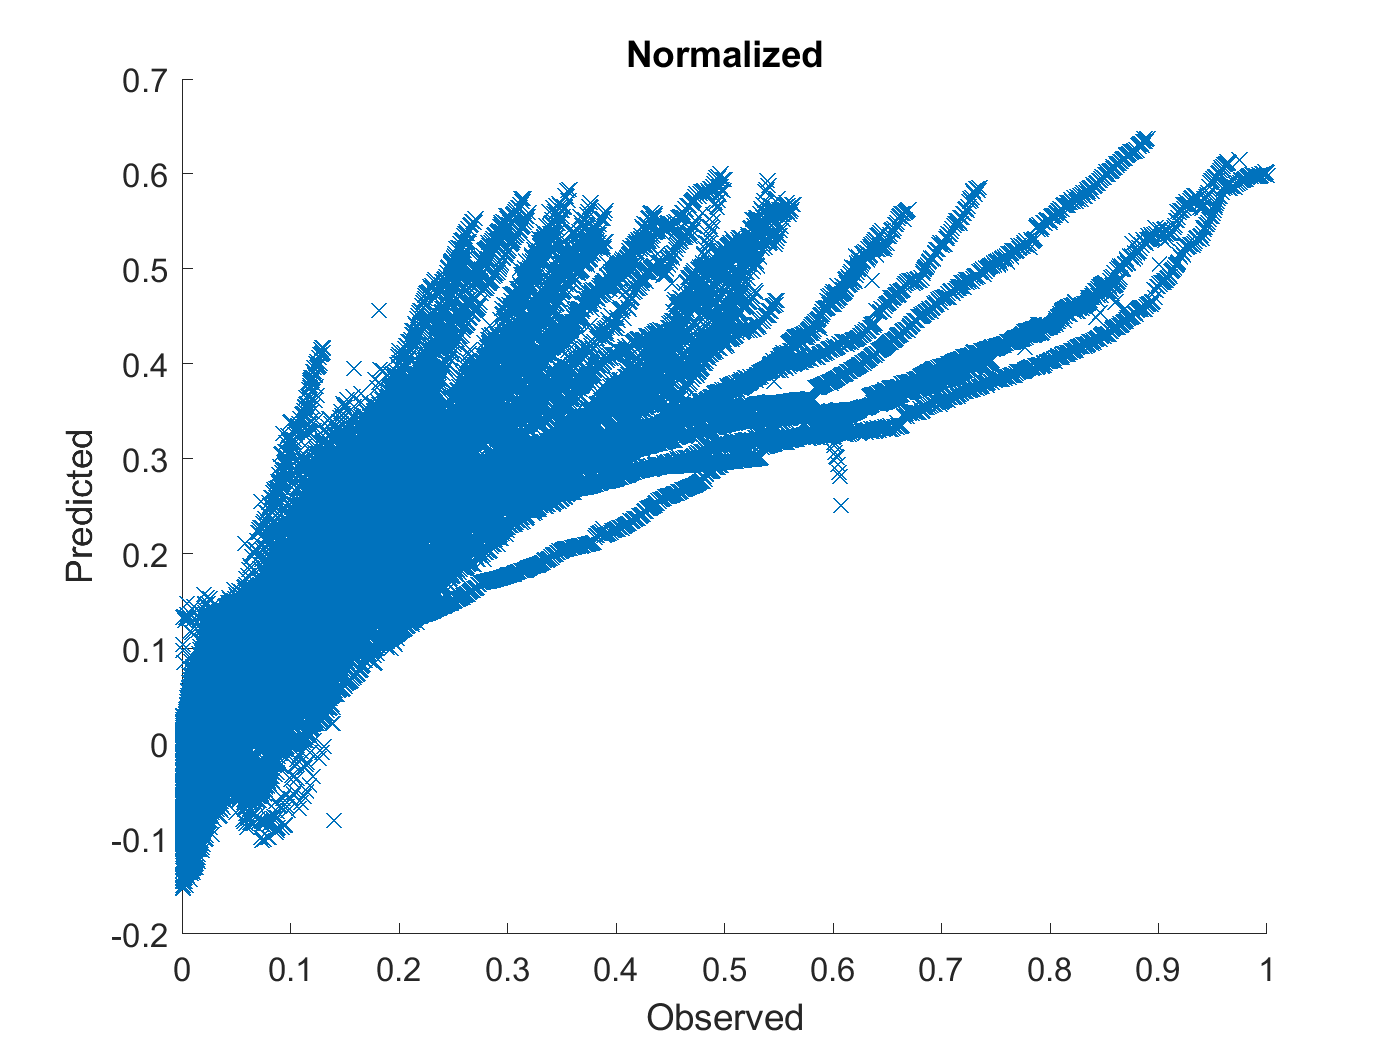


figure
hold on
plot(y_trainValid,yhat,'x')
xlabel("Observed")
ylabel("Predicted")
hold off
title 'Normalized'

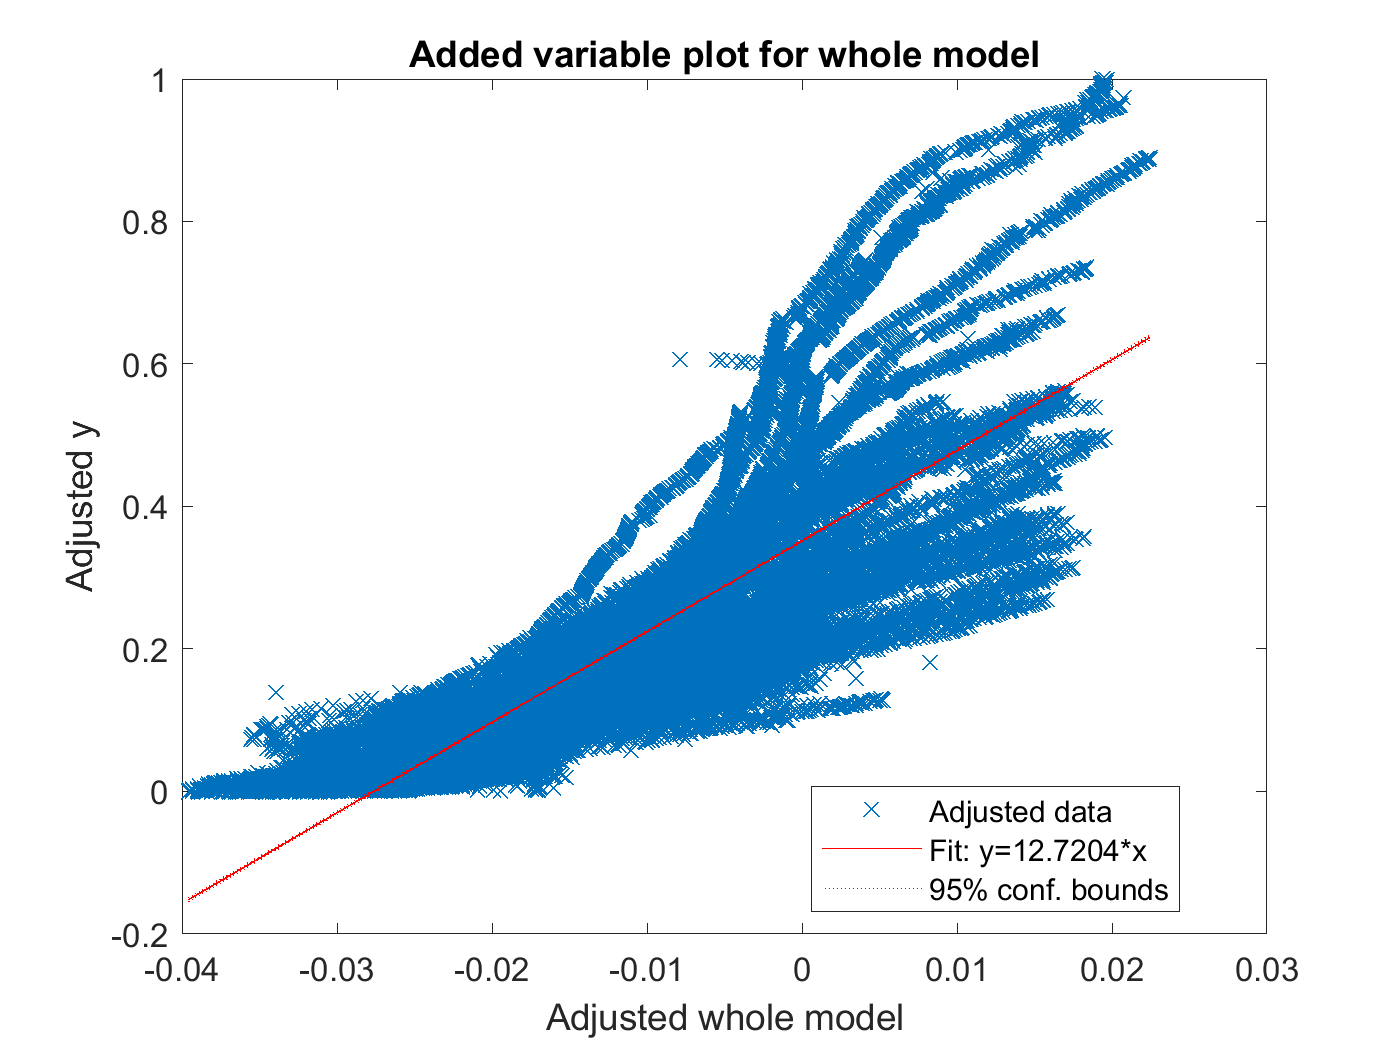

%{
figure
hold on
plot(y_trainValid,yhatr,'x')
xlabel("Observed")
ylabel("Predicted")
hold off
title 'Normalized'
%}
%capHat = Ic(1)

plot(mdl)

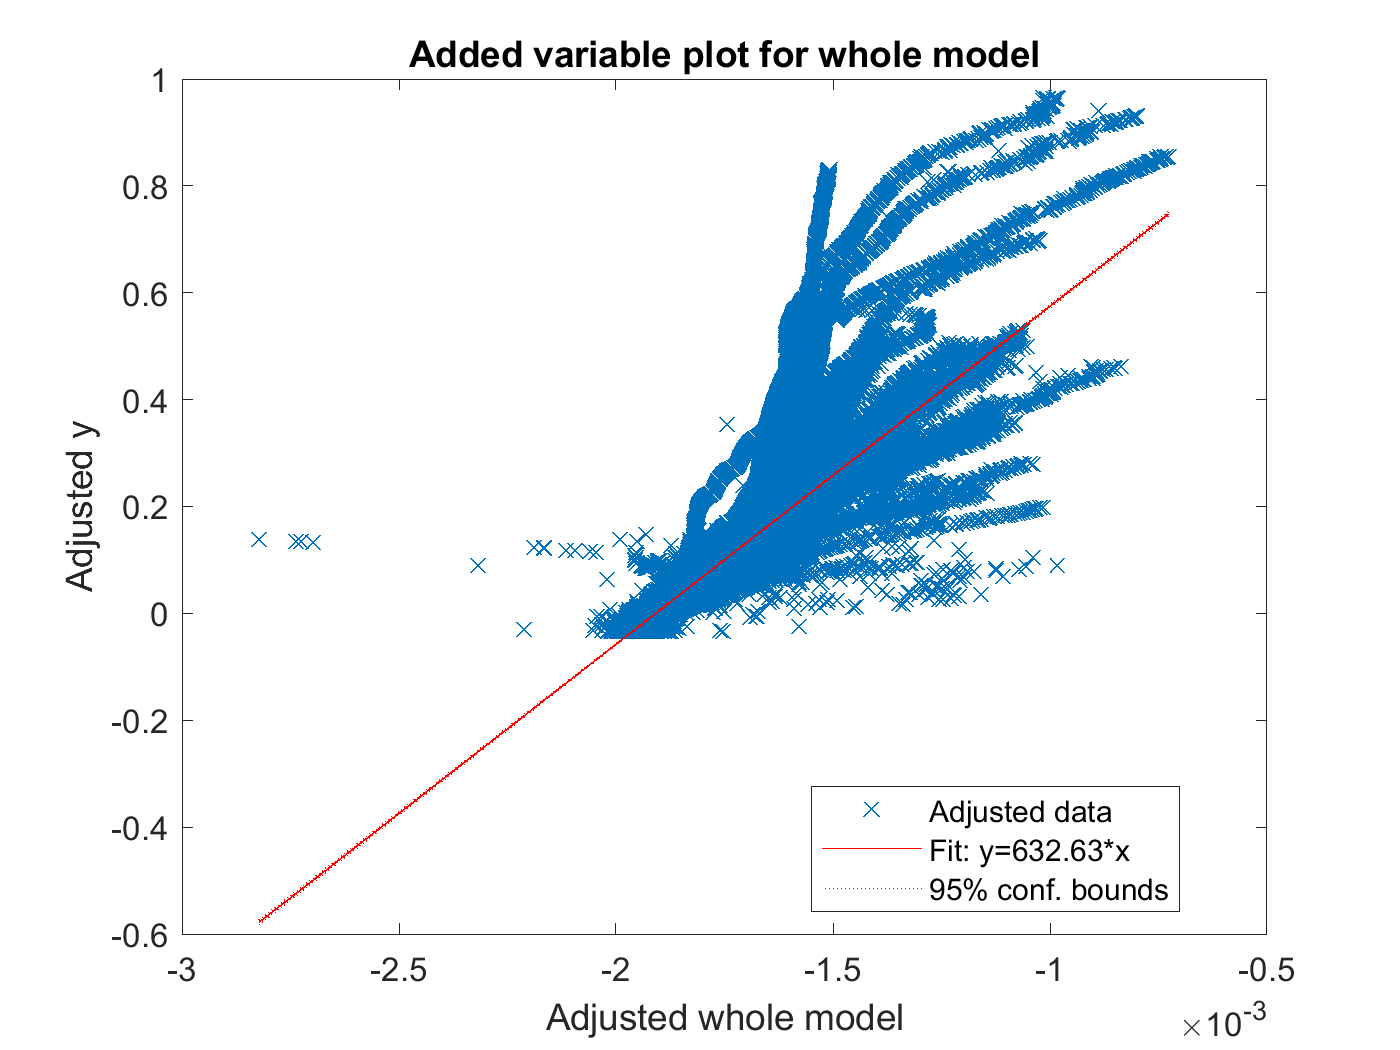

plot(mdlr)

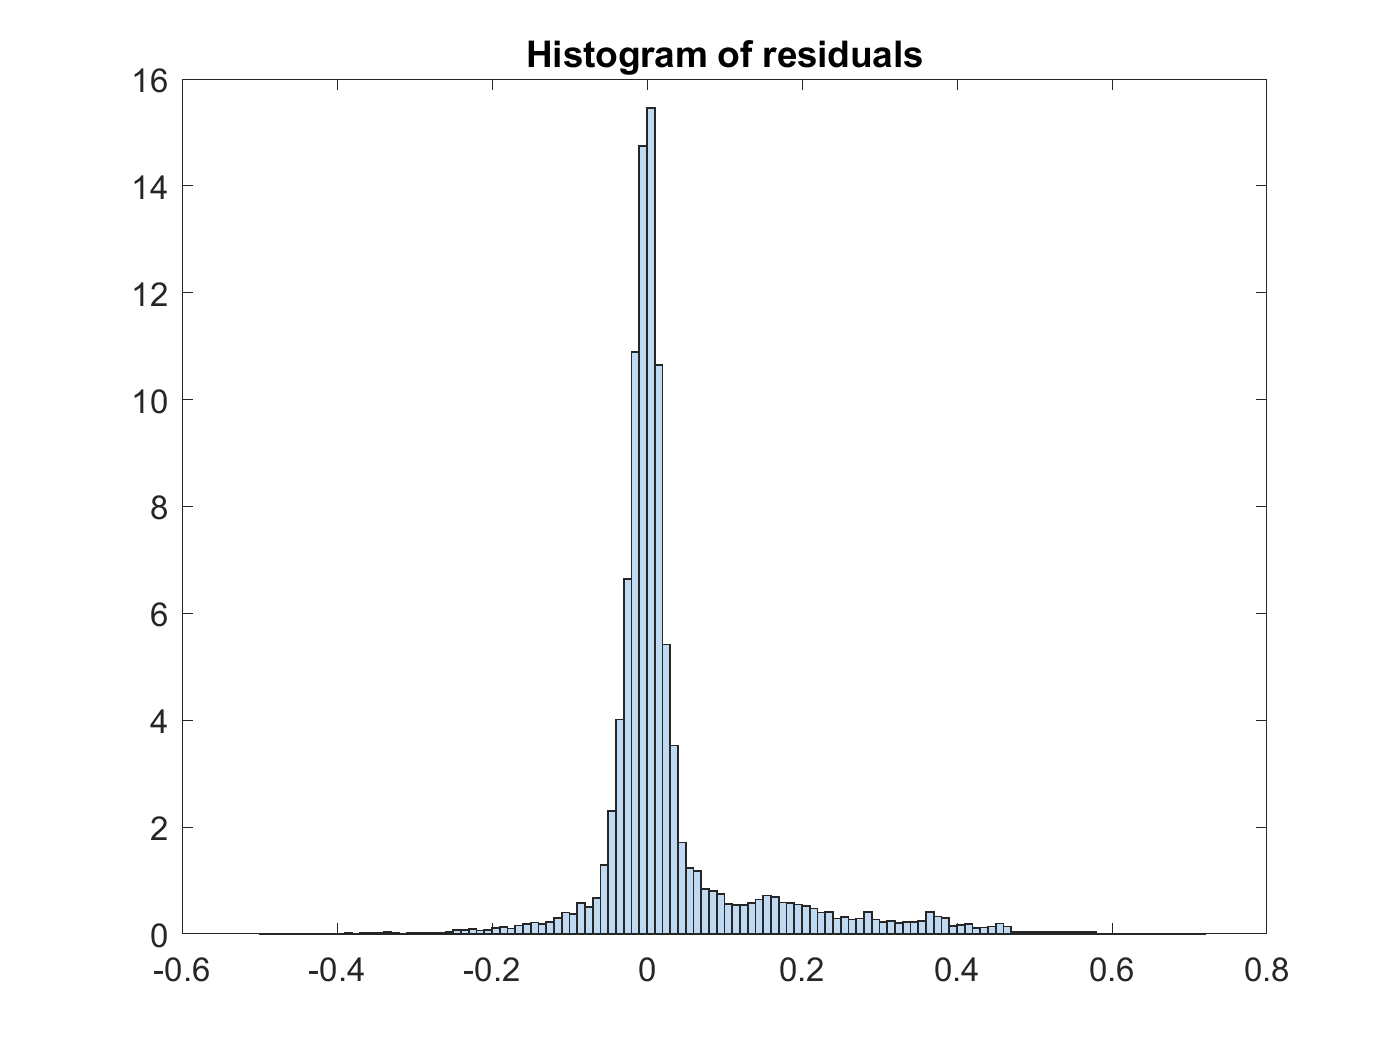

plotResiduals(mdlr)

plotResiduals(mdlr)




% yfit = predict(mdl,Ic)
yfit = predict(mdl,x_trainValid)

yfit =     0.4490
    0.4577
    0.4475
    0.4580
    0.4433
    0.4403
    0.4403
    0.4385
    0.4368
    0.4355


yfitr = predict(mdlr,x_trainValid)

yfitr =     0.4062
    0.4316
    0.4035
    0.4372
    0.3970
    0.3914
    0.3915
    0.3885
    0.3861
    0.3842


yfit_test = predict(mdl,x_test)

yfit_test =     0.3780
    0.3759
    0.3743
    0.3705
    0.3698
    0.3690
    0.3657
    0.3647
    0.3633
    0.3602


yfitr_test = predict(mdlr,x_test)

yfitr_test =     0.3761
    0.3737
    0.3718
    0.3678
    0.3672
    0.3660
    0.3626
    0.3592
    0.3557
    0.3503



y= y_trainValid

y =     0.3650
    0.3641
    0.3632
    0.3624
    0.3615
    0.3607
    0.3598
    0.3590
    0.3581
    0.3573



y_test

y_test = 	1.0e+03 *

    0.3160
    0.3150
    0.3140
    0.3130
    0.3120
    0.3110
    0.3100
    0.3090
    0.3080
    0.3070




% denormalize
yfit = yfit * yrate + ymin;
y = y * yrate + ymin;
yfit_test = yfit_test * yrate + ymin;
y_test = y_test * yrate + ymin;

yfitr = yfitr * yrate + ymin;
yfitr_test = yfitr_test * yrate + ymin;

MAE = mean(abs(yfit-y))

MAE = 87.2495

adjMAE = MAE/range(y)

adjMAE = 0.0746

range(y) % y = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 1170


(y - yhat)    % Errors

ans = 	1.0e+03 *

    0.4276
    0.4265
    0.4256
    0.4245
    0.4236
    0.4226
    0.4216
    0.4206
    0.4196
    0.4186


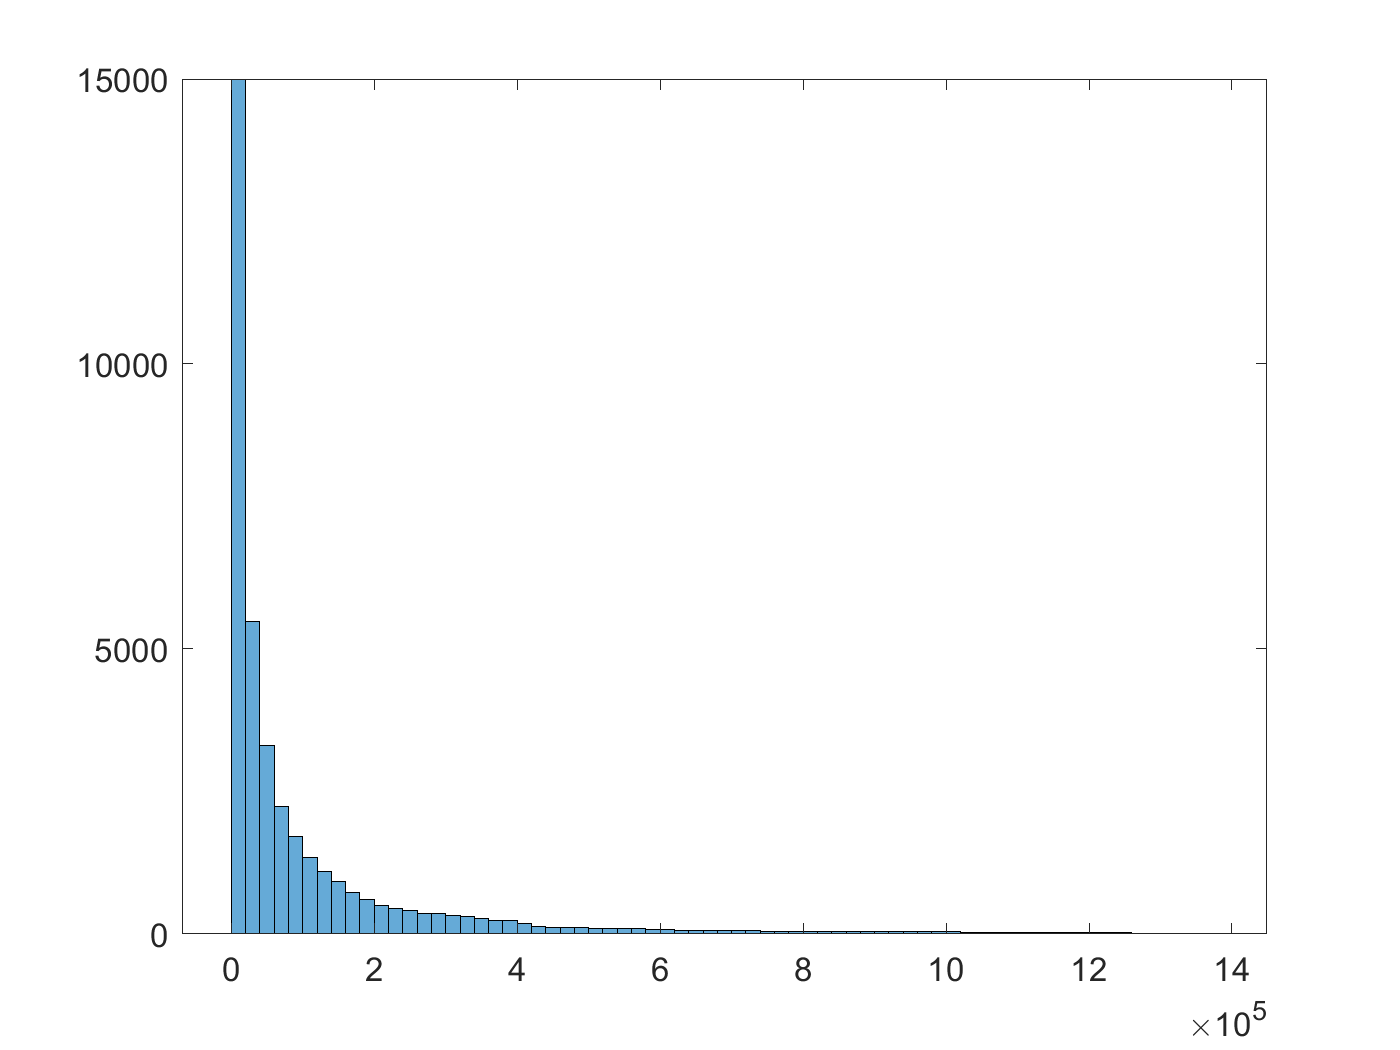

(y - yhat).^2;   % Squared Error
histogram((y - yhat).^2)

mean((y - yhat).^2);   % Mean Squared Error
RMSE = sqrt(mean((y - yhat).^2))  % Root Mean Squared Error

RMSE = 327.7725

RMSEr = sqrt(mean((y - yhatr).^2))

RMSEr = 328.5635

(y_test - yfit_test) 

ans = 	1.0e+06 *

    0.3693
    0.3681
    0.3669
    0.3658
    0.3646
    0.3634
    0.3623
    0.3611
    0.3599
    0.3588


RMSE_test = sqrt(mean((y_test - yfit_test).^2))

RMSE_test = 4.1012e+05

RMSEr_test = sqrt(mean((y_test - yfitr_test).^2))

RMSEr_test = 4.1014e+05

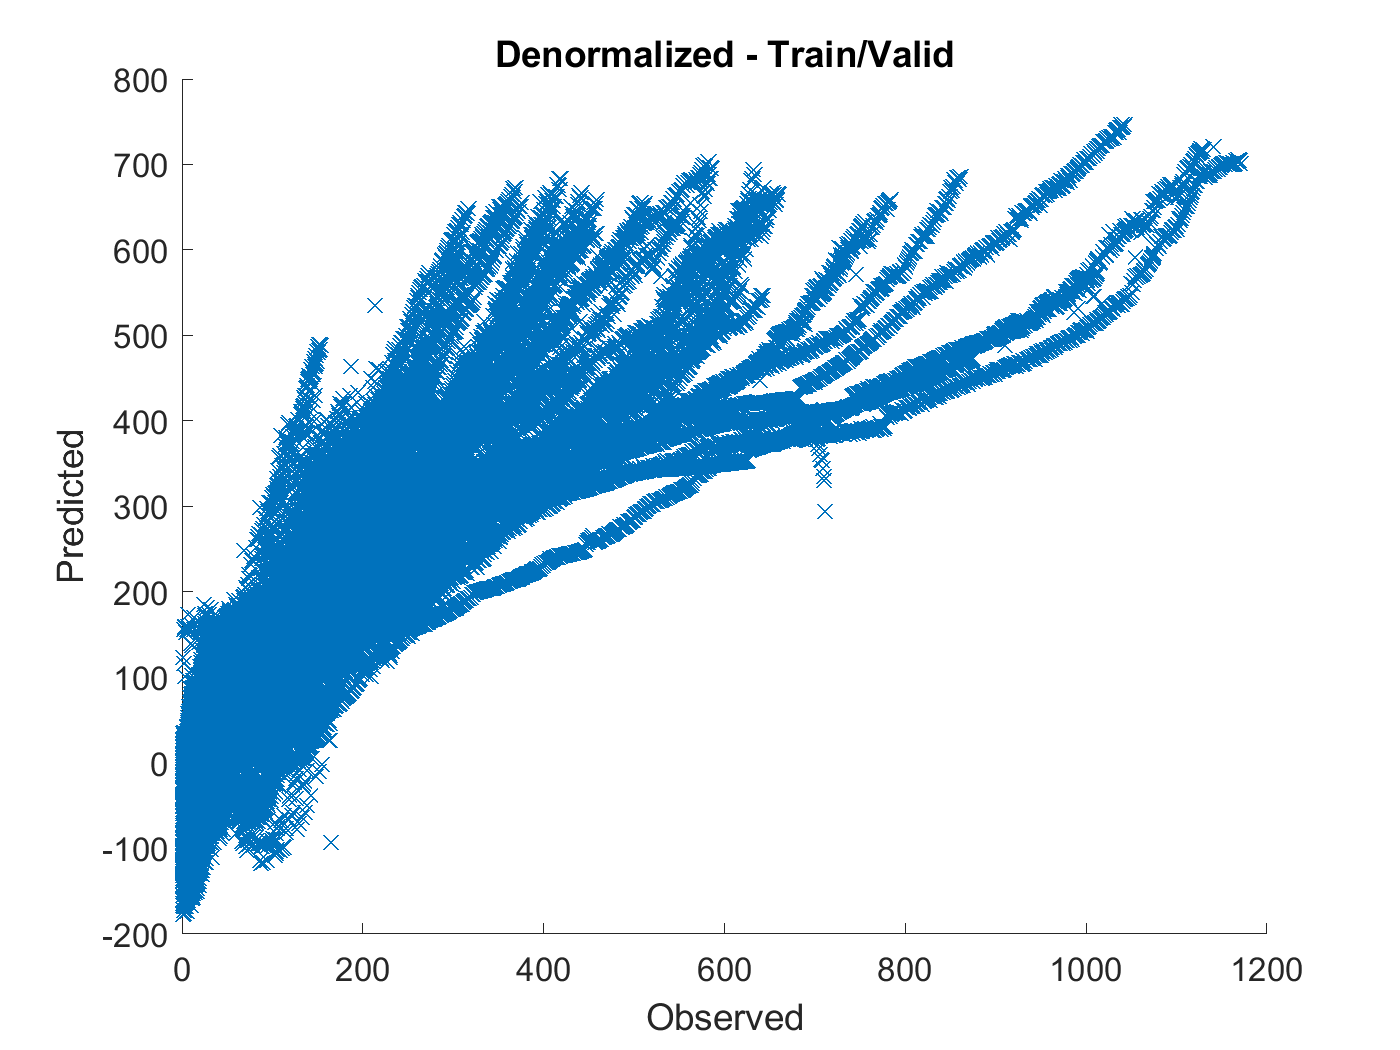


figure
hold on
plot(y,yfit,'x')
xlabel("Observed")
ylabel("Predicted")
hold off
title 'Denormalized - Train/Valid'

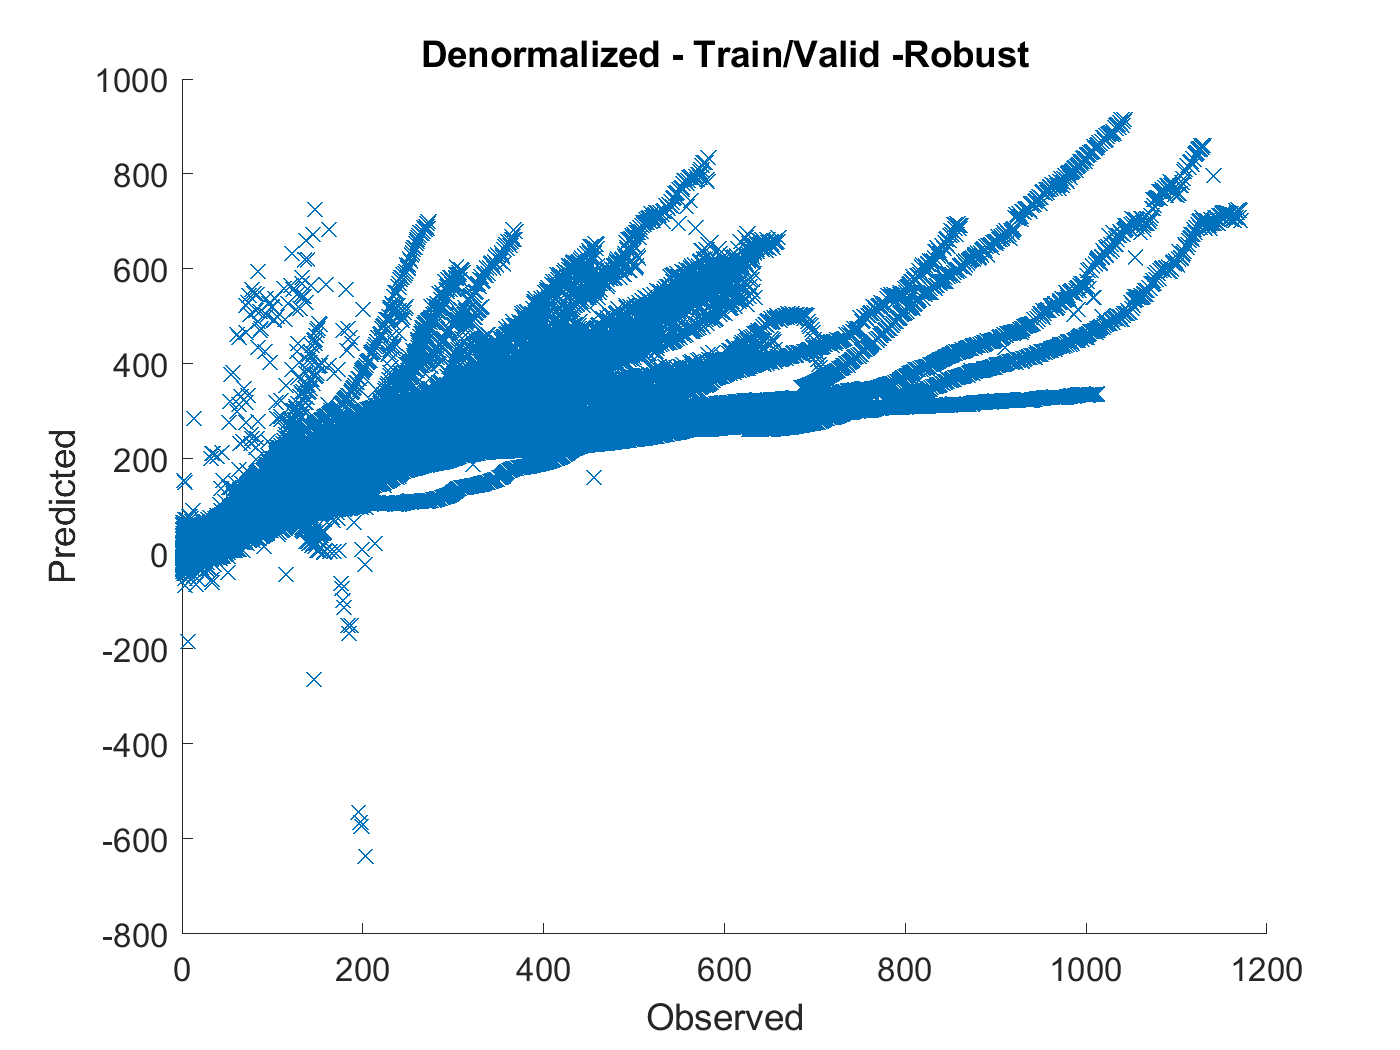

figure
hold on
plot(y,yfitr,'x')
xlabel("Observed")
ylabel("Predicted")
hold off
title 'Denormalized - Train/Valid -Robust'

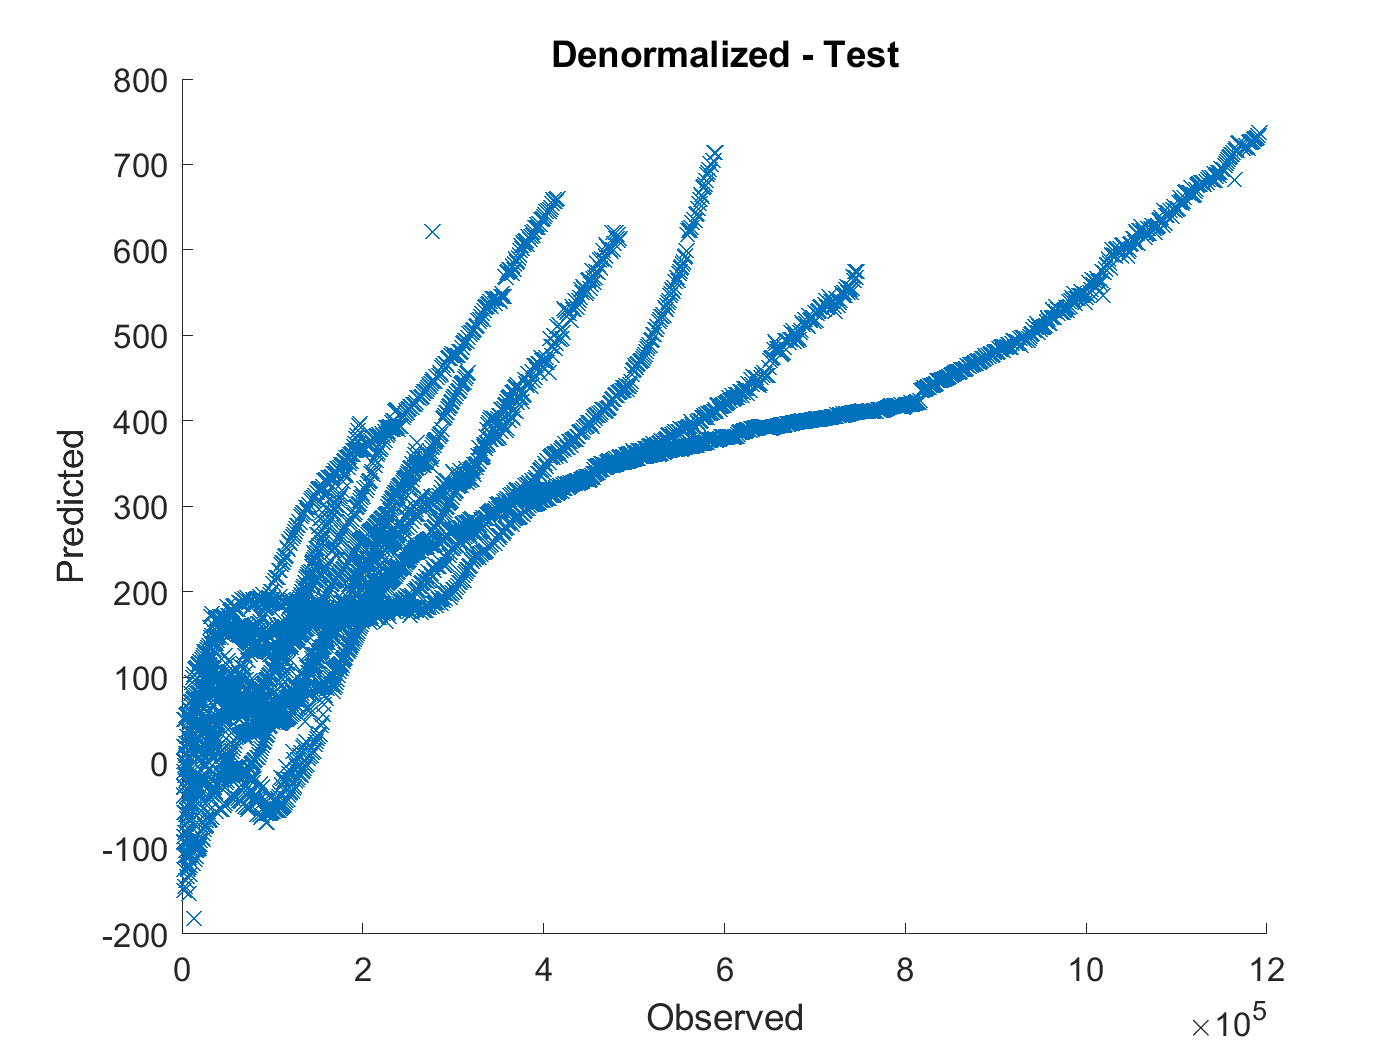


figure
hold on
plot(y_test,yfit_test,'x')
xlabel("Observed")
ylabel("Predicted")
hold off
title 'Denormalized - Test'

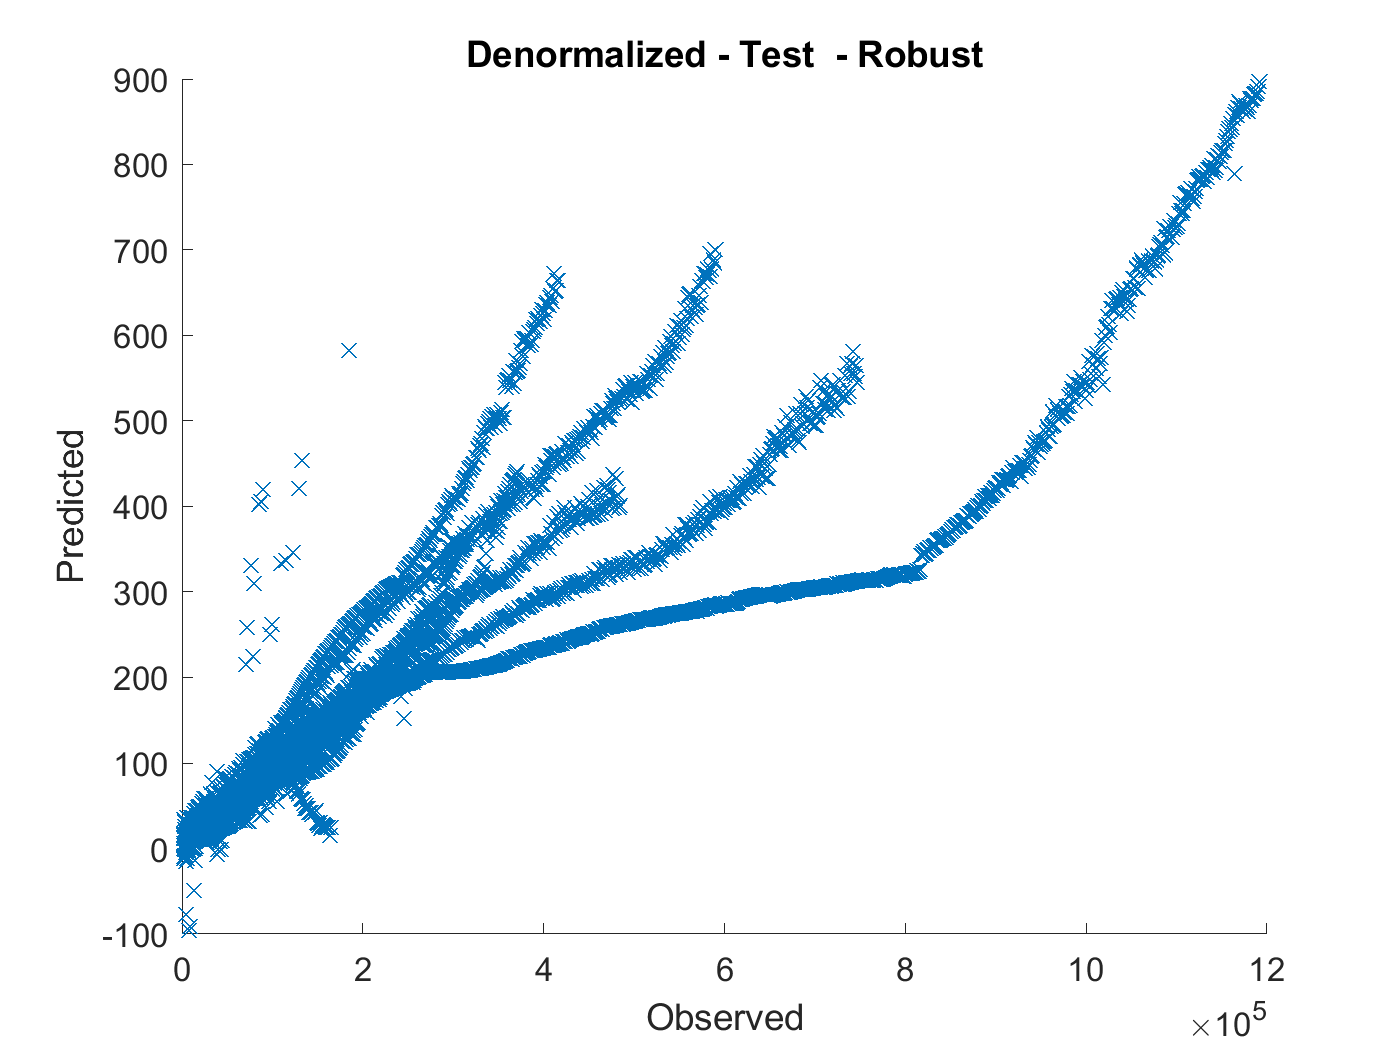

figure
hold on
plot(y_test,yfitr_test,'x')
xlabel("Observed")
ylabel("Predicted")
hold off
title 'Denormalized - Test  - Robust'


%xlim([0 1200]), ylim([0 1200])

% 테스트 셋에서는 예측이 전혀 안된다.
